## Step response with simulink model (LAB_0_sim.slx) with amplitude 360 deg (Point 2.1.2)

% Define the step amplitude vector

simul.select1 = 1;

step_gain = 360;
simOut_2_1_2 = sim('Lab_1\Point_2_1\2_1_2\Black_box_system_2_1_2.slx');

### Searching for referenced models in model 'Black_box_system_2_1_2'.
### Found 0 model reference targets to update.


Found algebraic loop that contains: 
Black_box_system_2_1_2/PID/Saturation  (discontinuity)
Black_box_system_2_1_2/Quanser SRV-02 + NI DAQ1/DAC/Zero-Order Hold
Black_box_system_2_1_2/Quanser SRV-02 + NI DAQ1/DAC/Quantizer (discontinuity)
Black_box_system_2_1_2/Quanser SRV-02 + NI DAQ1/DAC/Saturation (discontinuity)
Black_box_system_2_1_2/Quanser SRV-02 + NI DAQ1/Quanser SRV-02 (discontinuity)
<a href="matla

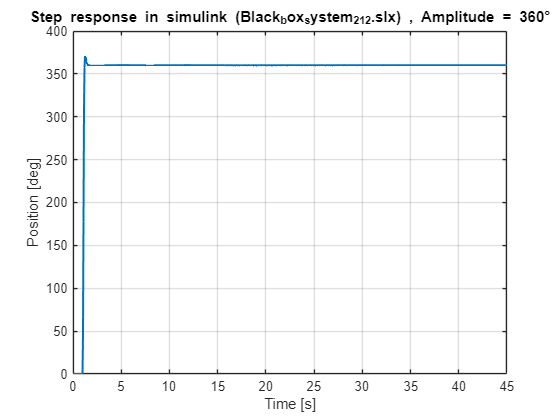


% Create plots
figure; 
plot(simOut_2_1_2.th.time,simOut_2_1_2.th.signals.values, 'LineWidth', 1.5);
grid on;
title(sprintf('Step response in simulink (Black_box_system_2_1_2.slx) , Amplitude = %d°', step_gain));
xlabel('Time [s]');
ylabel('Position [deg]');